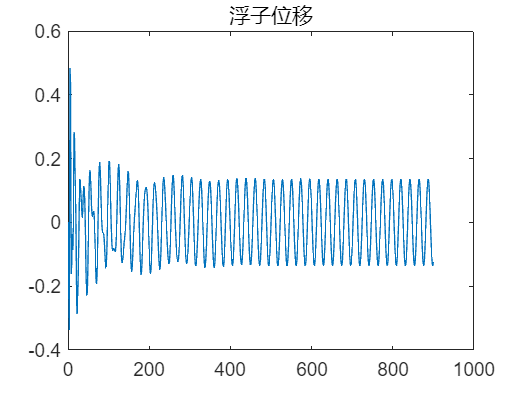

clc,clear
%initialize parameter

% r_f=1;                      %浮子底半径 (m)
% h_cast=3;                   %浮子圆柱部分高度 (m)
% h_cone=0.8;                 %浮子圆锥部分高度 (m)
% m_cast=m1*90/98;            %圆柱质量 (kg)
% V_cast=pi*r_f^2*h_cast;     %圆柱体积 (m3)
% m_cone=m1*8/90;             %圆锥质量 (kg)
% V_cone=1/3*h_cone*pi*r_f^2; %圆锥体积(m3)
% V_max=V_cone+V_cast;        %浮子体积
% r_v=0.5;                    %振子半径 (m)
% m_add=1335.535;             %垂荡附加质量 (kg)
% G1=m1*g;                    %浮子重力  (N)
% G2=m2*g;                    %振子重力  (N)
% kr=656.3616;                %垂荡兴波阻尼系数 (N·s/m)
% k=10000;                    %阻尼系数
% f_max=6250;                 %垂荡激励力振幅 (N)

L=2.3-2/15;                 %重心距底端距离
ke=80000;                   %弹簧刚度 (N/m)
g=9.8;                      %重力加速度 (m/s2)
l0=0.5;                     %弹簧原长 (m)
rho=1025;                   %海水的密度 (kg/m3)
m1=4866;                    %浮子质量 (kg)
m2=2433;                    %振子质量 (kg)
w=1.4005;                   %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                
dt=0.2;                     %步长设为0.2s
T=2*pi/w;                   %波浪周期（s)   
T_end=40*T;                 %总数值模拟时间(s)        
iter_times=ceil(T_end/dt);  %总迭代次数 
%l=zeros(iter_times,1);
%%初值设置
V0=(m1+m2)/rho;             %初始沉入水中体积(m3)
l=l0-m2*g/ke;            %弹簧的初始长度 (m)
%v1=l;
v1=0;                    %浮子的初始速度 (m/s)
%v2=l;
v2=0;                    %振子的初始速度 (m/s)
%x_f=l;
x_f=0;                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
%x_v=l;  

x_v=-(L-0.8-l(1));       %振子的初始位移 (m)
h=2.8-L;                    %水面的高度(m)

delta_x=l;
delta_x(1)=l(1);
X=zeros(4,iter_times);
X(:,1)=[x_f;x_v;v1;v2];
t=0;
X(:,2)=X(:,1)+dt*S_diff_equ(X(:,1),t);
for i=1:iter_times+1
    t=(i-1)*dt;
    % v1(i+1)=v1(i)+dt*(G1-ca_f_r(k,v1(i),v2(i))-kr*v1(i) ...
    %     -ca_f_e(ke,l(i),l(1))+f_max*cos(w*t) ...
    %     -ca_f_float(rho,g,x_f(i),L,V0,V_max,r_f,h))/(m1+m_add);%or -f*cos(wt)
    % v2(i+1)=v2(i)+dt*(G2+ca_f_r(k,v1(i),v2(i)) ...
    %     +ca_f_e(ke,l(i),l(1)))/m2;
    % x_f(i+1)=x_f(i)+(v1(i)+v1(i+1))/2*dt;
    % x_v(i+1)=x_v(i)+(v2(i)+v2(i+1))/2*dt;
    % l(i+1)=l0+x_f(i+1)-x_v(i+1);    
    K1=S_diff_equ(X(:,i),t);
    K2=S_diff_equ(X(:,i)+K1*dt/2,t+dt/2);
    K3=S_diff_equ((X(:,i)+K2*dt/2),t+dt/2);
    K4=S_diff_equ((X(:,i)+K3*dt),t+dt);
    X(:,i+1)=X(:,i)+dt/6*(K1+2*K2+2*K3+K4);
    %delta_x(i+1)=(v1(i+1)-v2(i+1))*dt;
end
plot(X(1,:))
title('浮子位移')
hold off

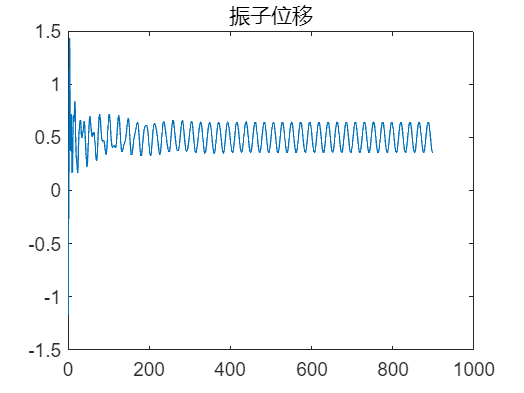

plot(X(2,:))
title('振子位移')
hold off

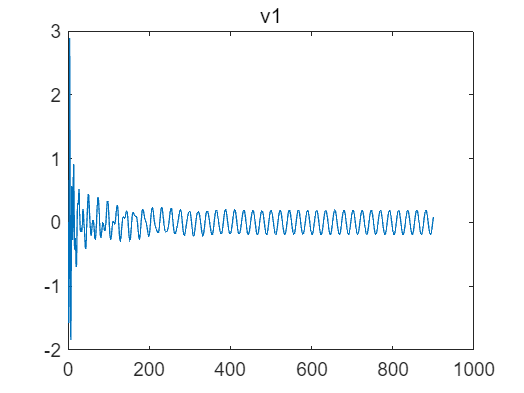

plot(X(3,:))
title('v1')
hold off

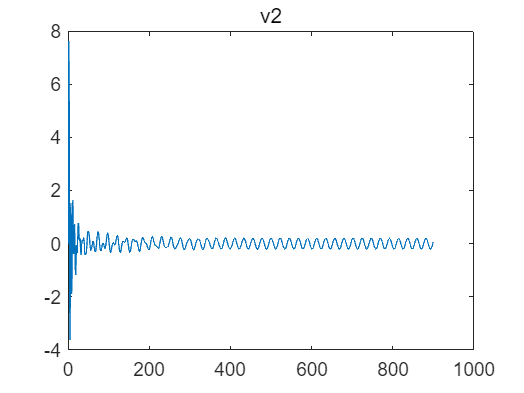

plot(X(4,:))
title('v2')
hold off

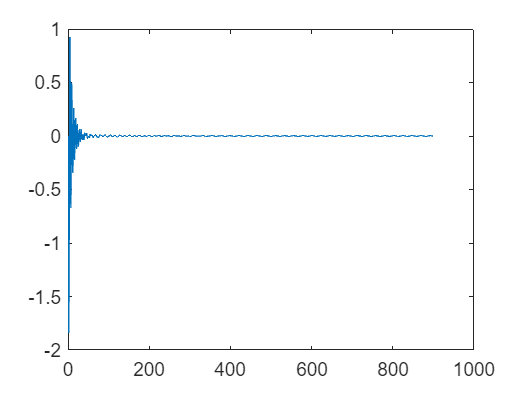

x=X(3,:)*dt-X(4,:)*dt;
plot(x)

% plot(abs(delta_x))

function f=ca_f_float(rho,g,x,L,V0,V_max,r_cost)
    %计算浮力   
    if x>=1
        V=V_max;
    elseif x>0.8-L&&x<1
        V=V0+x*2*pi*r_cost^2; 
    elseif x<(-L+0.8)&&x>-L
        V=1/3*rho*g*(L-0.8+x)^3*(0.8/r_cost)^2*pi;
    else 
        V=0;
    end
    f=rho*g*V;
end
function dxdt=S_diff_equ(X,t)
    x1=X(1);
    x2=X(2);
    v1=X(3);
    v2=X(4);
    m1=4866;                    %浮子质量 (kg)
    r_f=1;                      %浮子底半径 (m)
    h_cast=3;                   %浮子圆柱部分高度 (m)
    h_cone=0.8;                 %浮子圆锥部分高度 (m)
    V_cast=pi*r_f^2*h_cast;     %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2; %圆锥体积(m3)
    V_max=V_cone+V_cast;        %浮子体积
    m2=2433;                    %振子质量 (kg)
    m_add=1335.535;             %垂荡附加质量 (kg)
    g=9.8;                      %重力加速度 (m/s2)
    G1=m1*g;                    %浮子重力  (N)
    G2=m2*g;                    %振子重力  (N)
    rho=1025;                   %海水的密度 (kg/m3)
    ke=80000;                   %弹簧刚度 (N/m)
    l0=0.5;                     %弹簧原长 (m)
    w=1.4005;                   %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr=656.3616;                %垂荡兴波阻尼系数 (N·s/m)
    k=10000;                    %阻尼系数
    f_max=6250;                 %垂荡激励力振幅 (N)
    l=l0-m2*g/ke;               %弹簧的初始压缩量
    V0=(m1+m2)/rho;             %初始沉入水中体积(m3)
    L=2.3-2/15;                 %重心距底端距离
    r_cost=1;                   %浮子底半径 (m)
    k=k*abs(v1-v2)^1/2;
    % dxdt=[v1;
    %     v2;
    %     (G1-kr*(v1-v2)-ke*(x1-x2+l)-kr*v1-f_max*cos(w*t)-k*v1-ca_f_float(rho,g,x1,L,V0,V_max,r_cost))/(m1+m_add);
    %     (G2+kr*(v1-v2)+ke*(x1-x2+l))/m2];
    dxdt=[v1;
        v2;
        (G1-kr*(v1-v2)-ke*(x1-x2+l)-kr*v1-f_max*cos(w*t)-k*v1-ca_f_float(rho,g,x1,L,V0,V_max,r_cost))/(m1+m_add);
        (G2+kr*(v1-v2)+ke*(x1-x2+l))/m2];
    
end